# **Matlab homework (lab 2)**

 clear; close all;
% insert your names and IDs here
Name{1} = 'Nerea Rabaixet';
NIA{1} = 229968;
Name{2} = 'Nasar Roca';
NIA{2} = 231676;

load dataset.mat

If you take the full dataset (dataset.mat), the size is 257468 samples.

The specific datasets of places are in locations folder. The size is not too large, but you get different results dpending on the location you use.

"dataset.mat"

"locations/GoldCoast_dataset.mat" (You can change the location.)

# QUESTION 2

% Enter code for question 2 here
N = size(D,1)

N = 255174

X1 = D(:,1); meanX1 = mean(X1);
X2 = D(:,2); meanX2 = mean(X2);
Y = D(:,3); meanY = mean(Y);

X = [ones(N,1) X1 X2];
B = beta(X1,X2,Y)

B =   377.6508
   -0.1702
   -0.3423


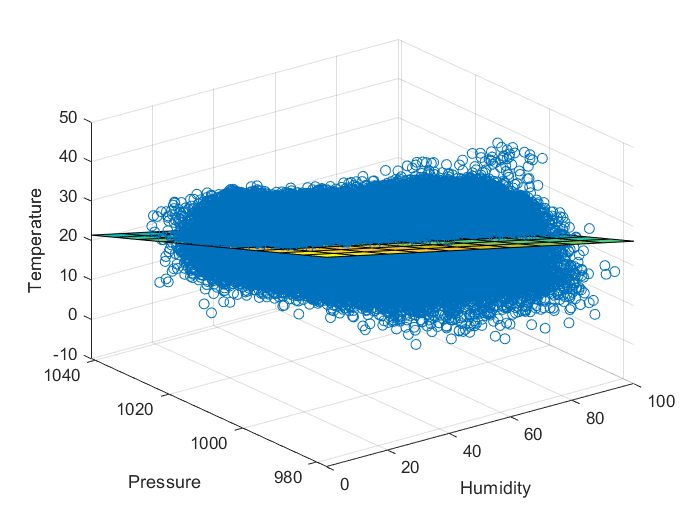

print(X1,X2,Y);

Finding betas and doing the plot of our data.

# QUESTION 3

% write your code here code
alpha  = 0.05;
k = 2;
SStot = 0; SSreg = 0;
for i = 1:N
    SStot = SStot + (Y(i) - meanY)^2;
    Yreg = B(1) + B(2)*X1(i) + B(3)*X2(i);
    SSreg = SSreg + (Yreg - meanY)^2;
end
SSerr = SStot - SSreg;
R_squared = SSreg/SStot

R_squared = 0.4555

check_quality(R_squared);

We cannot say nothing about data quality.



disp('-----F_TEST-----');

-----F_TEST-----


F_crit = finv(1 - alpha,k,N-k-1) % One sided

F_crit = 2.9958

F_obs = (SSreg/k)/(SSerr/(N-k-1))

F_obs = 1.0673e+05

if F_obs <= F_crit
    disp('H0 is accepted then Y is not correlated with any regressor Xi')
else
    disp('H0 is rejected then Y is correlated with at least one regresson Xi')
end

H0 is rejected then Y is correlated with at least one regresson Xi


disp(['P-value = ', num2str(1 - fcdf(F_obs,k,N-k-1))]);

P-value = 0


Checking the quality of the data and doing the F-test.

# QUESTION 4

% write your code here

ss = SSerr/(N-k-1);
mat = inv(X' * X) * ss;

Sbeta1 = sqrt((SSerr*mat(2,2)/(N-k-1)));
Sbeta2 = sqrt((SSerr*mat(3,3)/(N-k-1)));

T_crit = tinv(1-(alpha/2),N-k-1)

T_crit = 1.9600


disp('-----T_TEST_1-----');

-----T_TEST_1-----


T_crit = tinv(1-(alpha/2),N-k-1)

T_crit = 1.9600

Tobs1 = (B(2)-0)/Sbeta1

Tobs1 = -68.8988

if (abs(Tobs1) <=  T_crit)
    disp('H0_1 is accepted then X1 has not an effect on Y')
else
    disp('H0_1 is rejected then X1 have effect on Y')
end

H0_1 is rejected then X1 have effect on Y


P_value1 = 2*(1-tcdf(abs(Tobs1),N-k-1));
disp(['P-value_1 = ', num2str(P_value1)]);

P-value_1 = 0



disp('-----T_TEST_2-----');

-----T_TEST_2-----


T_crit = tinv(1-(alpha/2),N-k-1)

T_crit = 1.9600

Tobs2 = (B(3)-0)/Sbeta2

Tobs2 = -45.9724

if (abs(Tobs2) <= T_crit)
    disp('H0_2 is accepted then X2 has not an effect on Y')
else
    disp('H0_2 is rejected then X2 have effect on Y')
end

H0_2 is rejected then X2 have effect on Y


P_value2 = 2*(1-tcdf(abs(Tobs2),N-k-1));
disp(['P-value_2 = ', num2str(P_value2)]);

P-value_2 = 0


Doing the T-test for both regressors.

function result = beta(X1,X2,Y)
    N = size(Y,1);
    X = [ones(N,1) X1 X2];
    result = (X' * X)  \ (X' * Y);
end

function print(X1,X2,Y)
    B = beta(X1,X2,Y);
    dx1 = max(X1)-min(X1);
    dx2 = max(X2)-min(X2);
    x4plane = (min(X1):dx1/10:max(X1))';
    y4plane = (min(X2):dx2/10:max(X2))';
    z4plane = zeros(size(y4plane,1),size(x4plane,1));
    for i = 1:size(x4plane,1)
        for j = 1:size(y4plane,1)
            z4plane(j,i) = B(1) + x4plane(i) * B(2) + y4plane(j) * B(3);
        end
    end
    surf(x4plane,y4plane,z4plane);
    xlabel('Humidity');
    ylabel('Pressure');
    zlabel('Temperature');
    hold on
    scatter3(X1,X2,Y);
end

function check_quality(R_squared)
    if R_squared >= 0.8
        disp('The data has high quality.');
    elseif R_squared < 0.2
        disp('The data has poor quality.');
    else 
        disp('We cannot say nothing about data quality.');
    end
end